# Clean Messy Data and Locate Extrema Using Live Editor Tasks

You can interactively preprocess data using sequences of Live Editor tasks, visualizing the data at each step. This example uses five tasks to clean noisy data with missing values and outliers in order to identify local minima and maxima. For more information on Live Editor tasks, see [Add Live Editor Tasks to a Live Script](docid:matlab_prog#mw_85b9fce4-395e-4d16-8181-8160b823d703).

First, create and plot a vector of messy data, which contains four `NaN` values and five outliers.

clear; clc; close all;
format short eng
load('E2038.mat');   % Suppose data is in a variable pz
data = p(:,1);      % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;
% Optional: Mean-subtraction to remove DC offset/baseline
data = data - mean(data(1:10));

To plot the messy data, open the **Create Plot** task. Start by typing the keyword `plot` in a code block, and then click `Create Plot` when it appears in the menu. Select the plot type and input data to plot the data.

To see the code that this task generates, expand the task display by clicking   at the bottom of the task parameter area.

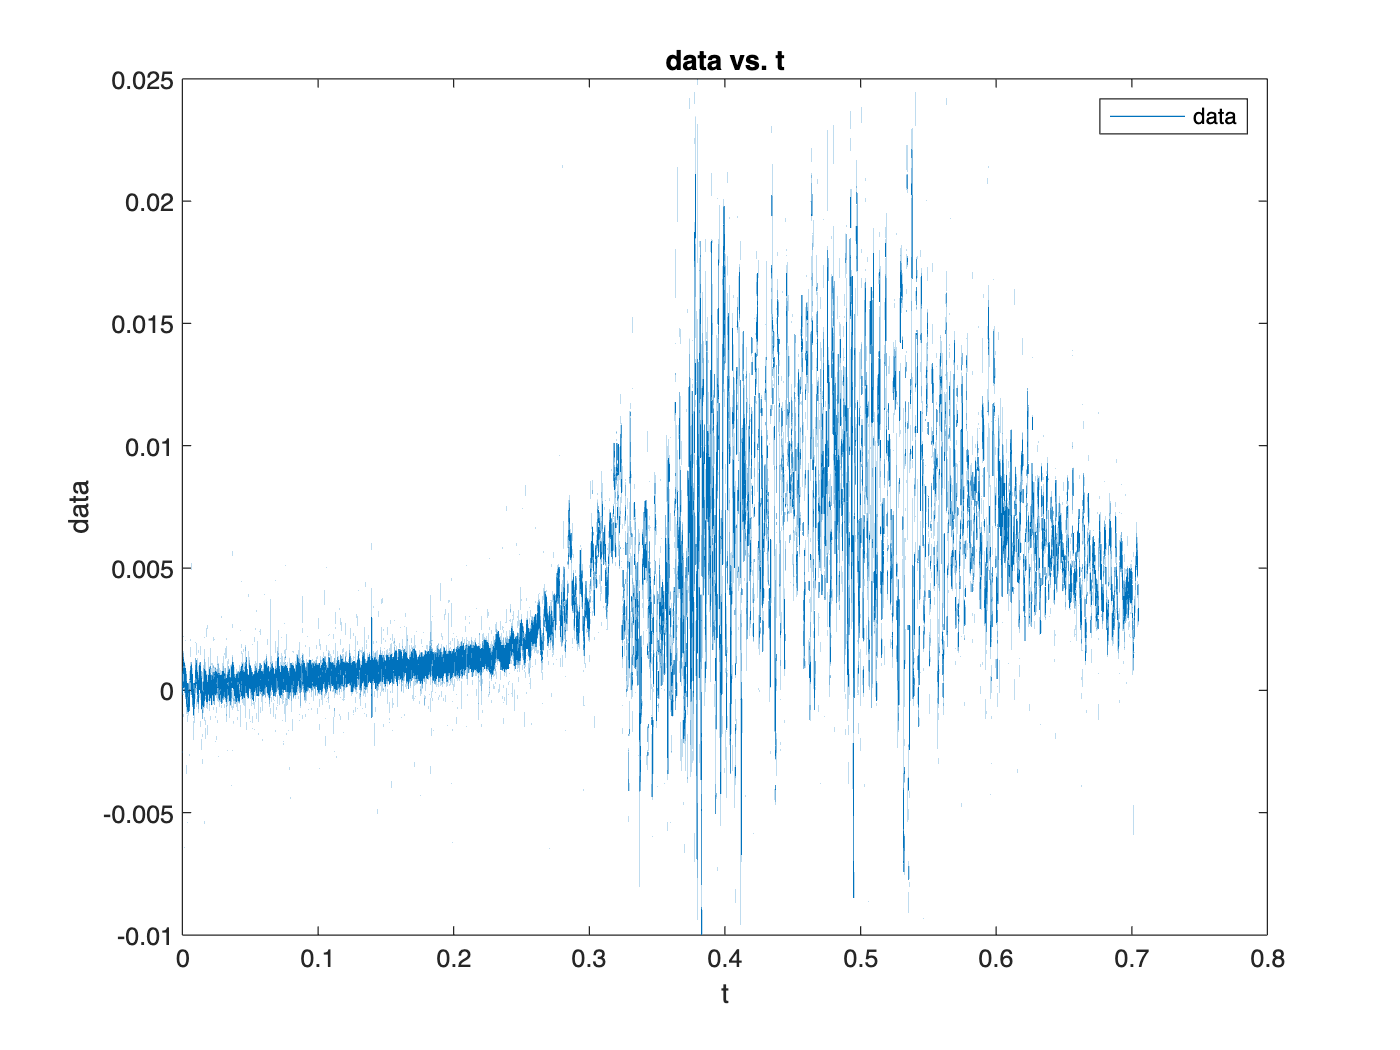

% Create plot of t and data
h = plot(t,data,"DisplayName","data");

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("data")
title("data vs. t")
legend

## Fill Missing Data

To replace `NaN` values in the data and visualize the results, open the **Clean Missing Data** task. Start by typing the keyword `missing` in a code block, and then click `Clean Missing Data` when it appears in the menu. Select the input data and the cleaning method to plot the filled data automatically.

To see the code that this task generates, expand the task display by clicking   at the bottom of the task parameter area.

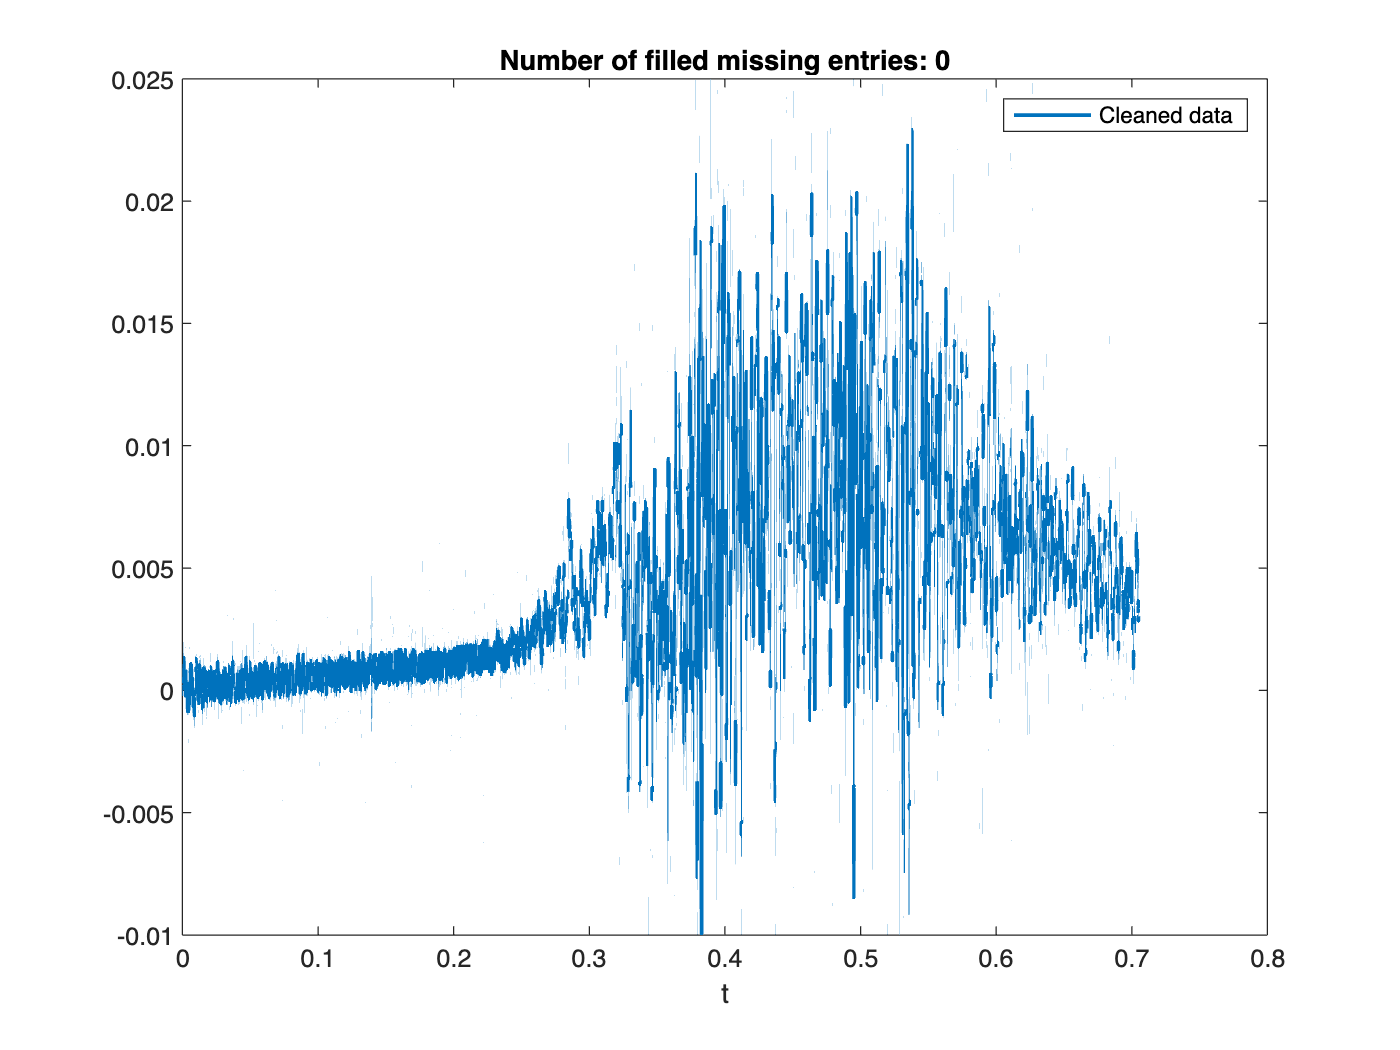

% Fill missing data
[cleanedData,missingIndices] = fillmissing(data,"linear","SamplePoints",t);

% Display results
figure

% Plot cleaned data
plot(t,cleanedData,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(t(missingIndices),cleanedData(missingIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend
xlabel("t")

clear missingIndices

## Fill Outliers

You can now remove the outliers from the cleaned data in the previous task by using the **Clean Outlier Data** task. Type the keyword `outliers` in a new code block and click `Clean Outlier Data` to open the task. Select `cleanedData` as the input data. You can customize the methods for cleaning and detecting outliers and adjust the threshold to find more or fewer outliers.

To see the code that this task generates, expand the task display by clicking   at the bottom of the task parameter area.

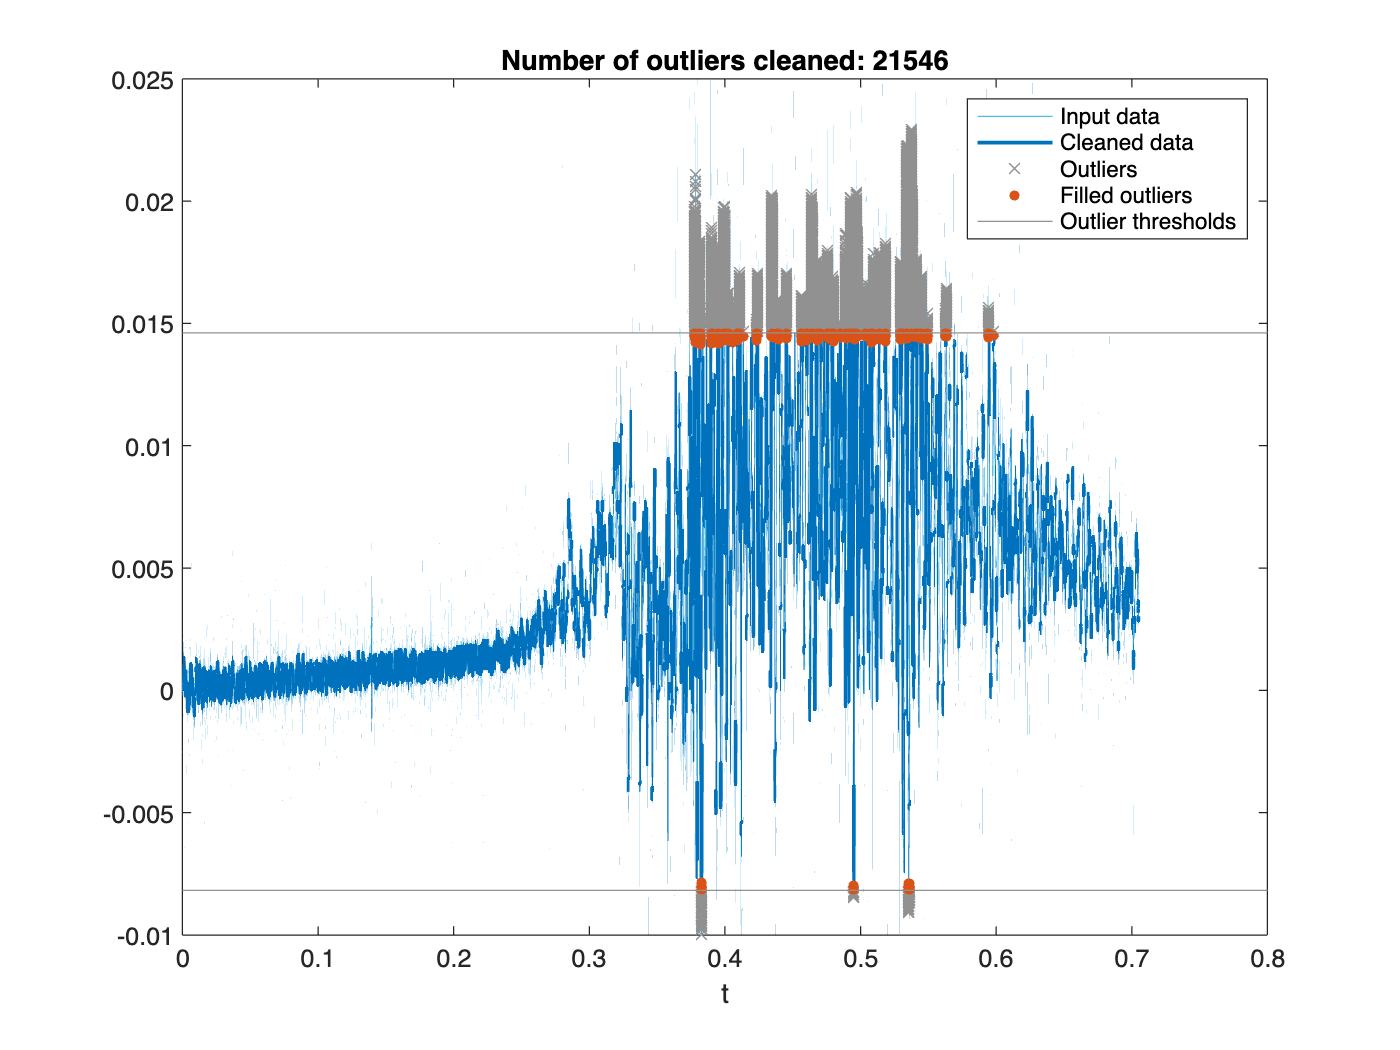

% Fill outliers
[cleanedData2,outlierIndices,thresholdLow,thresholdHigh] =  ...
    filloutliers(cleanedData,"linear","SamplePoints",t);

% Display results
figure
plot(t,cleanedData,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(t,cleanedData2,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")

% Plot outliers
plot(t(outlierIndices),cleanedData(outlierIndices),"x", ...
    "Color",[145 145 145]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(t(outlierIndices),cleanedData2(outlierIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]], ...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("t")

clear thresholdLow thresholdHigh

## Smooth Data

Next, smooth the cleaned data from the previous task by using the **Smooth Data** task. Type the keyword `smooth` and click the task when it appears. Select `cleanedData2`, the output from the previous task, as the input data. Select a smoothing method, and adjust the smoothing factor for more or less smoothing.

To see the code that this task generates, expand the task display by clicking   at the bottom of the task parameter area.

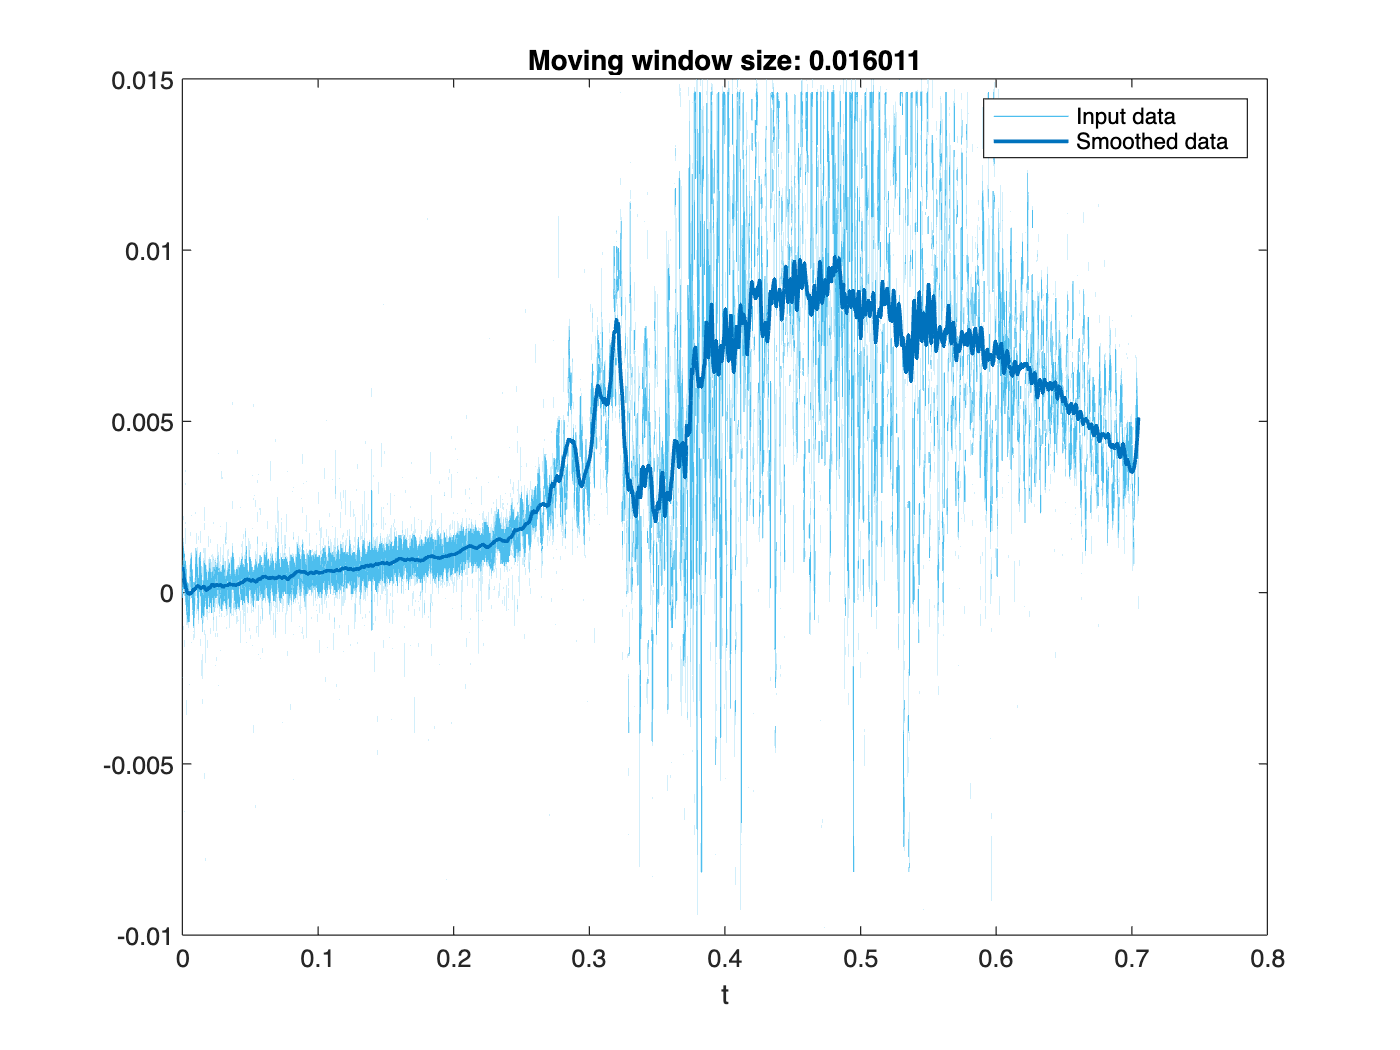

% Smooth input data
[smoothedData,winSize] = smoothdata(cleanedData2, ...
    "sgolay","SmoothingFactor",0.45,"Degree",3,"SamplePoints",t);

% Display results
figure
plot(t,cleanedData2,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(t,smoothedData,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
xlabel("t")

clear winSize

## Locate Extrema

Finally, start typing the keyword `extrema` and click `Find Local Extrema`. Use `smoothedData` as the input data and change the extrema type to find both the local maxima and local minima of the cleaned, smoothed data. You can adjust the local extrema parameters to find more or fewer maxima and minima.

To see the code that this task generates, expand the task display by clicking   at the bottom of the task parameter area.

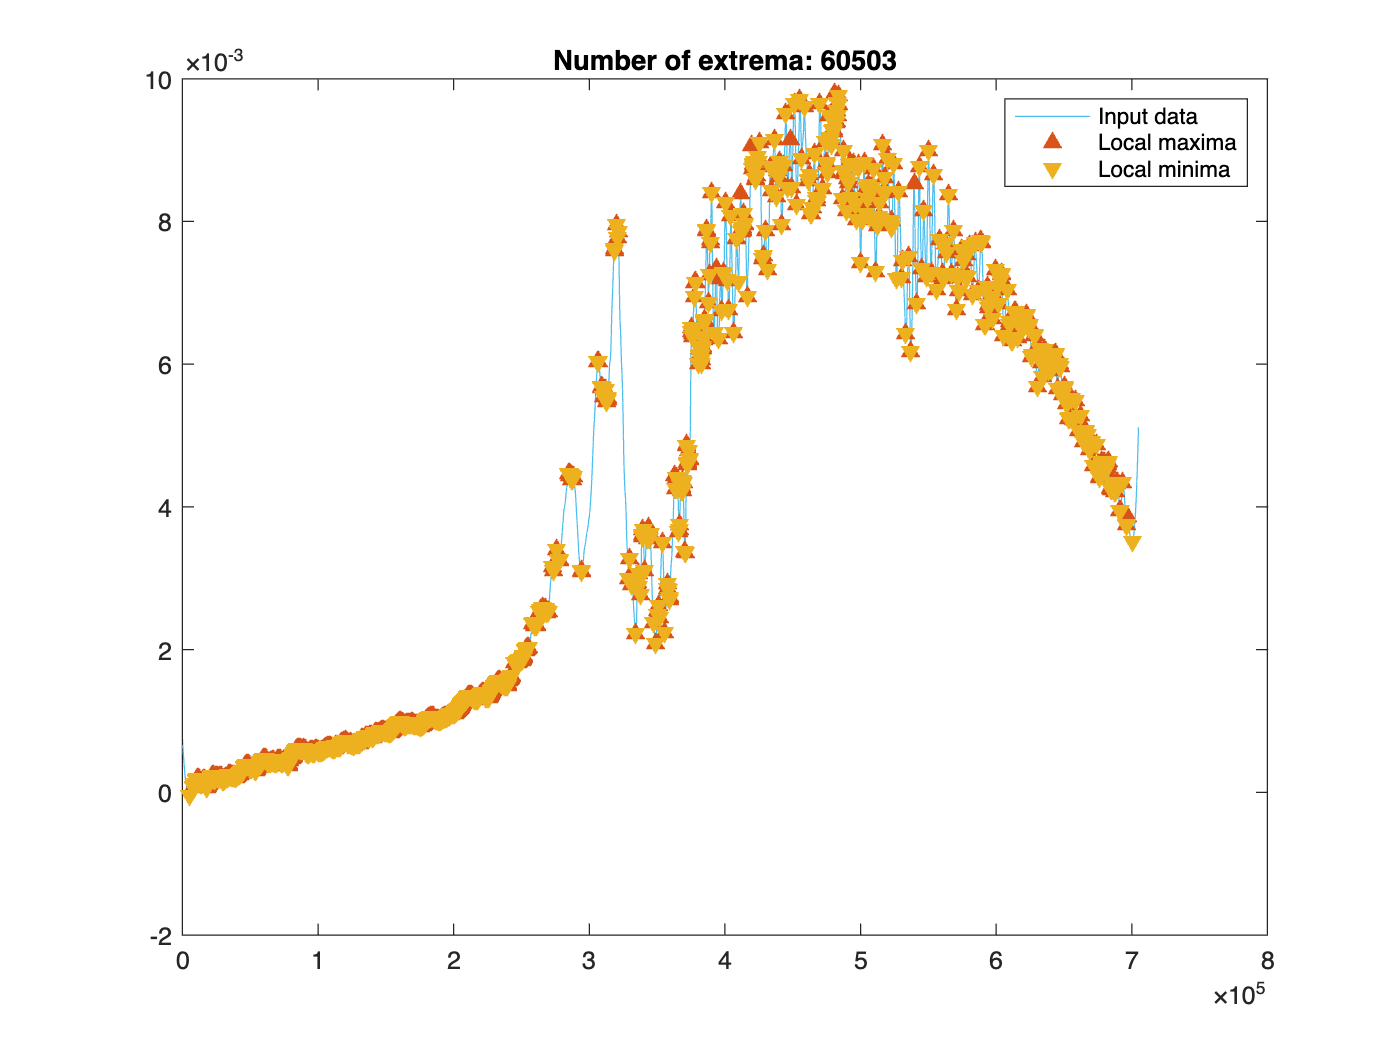

% Find local maxima and minima
maxIndices = islocalmax(smoothedData);
minIndices = islocalmin(smoothedData);

% Display results
clf
plot(smoothedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices),smoothedData(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")

% Plot local minima
plot(find(minIndices),smoothedData(minIndices),"v","Color",[237 177 32]/255,...
    "MarkerFaceColor",[237 177 32]/255,"DisplayName","Local minima")
title("Number of extrema: " + (nnz(maxIndices)+nnz(minIndices)))
hold off
legend

*Copyright 2022 The MathWorks, Inc.*